# Taller Filtros - Parte 2

#### Ana Sofia Aponte Barriga

#### Daniel Esteban Prieto Jiménez

#### José Alejandro Peñaranda Chia

# Filtros IIR

### Creación de los filtros

Como observamos en los filtros analógicos el filtro con mayor orden que se presento tuvo un valor de N=3. Esta informacion la usaremos para este ejercicio

N = 3 ;

#### Lo primero que hacemos es crear los filtros analógicos que vamos a transformar en filtros digitales,

#### G1

[N1, Wn1] = buttord(125*2*pi, 250*2*pi, 3, 15, 's');
[num1, den1] = butter(N, Wn1,'low', 's');

#### G2

[N2, Wn2] = buttord([125*2*pi, 500*2*pi], [62.5*2*pi, 1000*2*pi], 3, 15, 's');
[num2, den2] = butter(N, Wn2,'bandpass', 's');

#### G3

[N3, Wn3] = buttord([500*2*pi, 2000*2*pi], [250*2*pi, 4000*2*pi], 3, 15, 's');
[num3, den3] = butter(N, Wn3,'bandpass', 's');

#### G4

[N4, Wn4] = buttord([2000*2*pi, 8000*2*pi], [1000*2*pi, 16000*2*pi], 3, 15, 's');
[num4, den4] = butter(N, Wn4,'bandpass','s');

#### G5

[N5, Wn5] = buttord(8000*2*pi, 4000*2*pi, 3, 15, 's');
[num5, den5] = butter(N, Wn5, 'high', 's');

Una vez hecho esto se cargan las variables requeridas del audio a reproducir:

fsAudio = 64000 ;
load Audio1.mat
load Audio2.mat
[Audio3, fsmp3] = audioread("jour-1.mp3") ; % Acá se cambia el mp3
Audio3 = Audio3(:, 1) ;

### Espacio para seleccionar el audio

prueba = Audio2 ;
fs = fsAudio ;

### Transformación por invariancia del impulso

para usar la funcion impinvar es necesario calcular el equivalente de la frecuencia analoga a digital de la siguiente forma,


$$\frac{\textrm{fs}}{2\pi \;}=\frac{f_A }{f_D }\longrightarrow f_D =\frac{2\pi \;}{\textrm{fs}}f_A$$


una vez hecho esto, se usa la siguiente relación para calcular la frecuencia que ingresará a la funcion,


$$f_s =\frac{\omega_A }{\omega_D }$$


Para verificar el correcto funcionamiento del filtro la forma mas directa  es observar que a la frecuencia de interés se cumpla la atenuación deseada,

#### G1

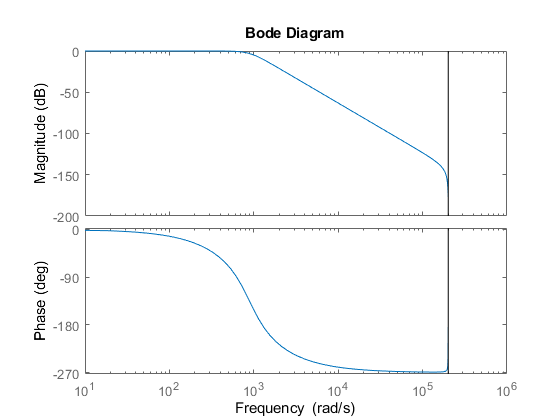

fs=64000;
w1 = (2*pi*125)/fs ;
fi1 = (2*pi*125)/w1 ;
[numz1, denz1] = impinvar(num1, den1, fi1);
sysz1=tf(numz1, denz1, 1/fs) ;
bode(sysz1)

Sabiendo que la funcion bode grafica es velocidad angular y no frecuencia debemos multiplicar por 2pi la frecuencia angular, una vez hecho esto podemos observar que se cumplan las frecuencia de corte.

Para este caso la frecuencia de corte es de 125 Hz lo que equivale a 785 rad/s.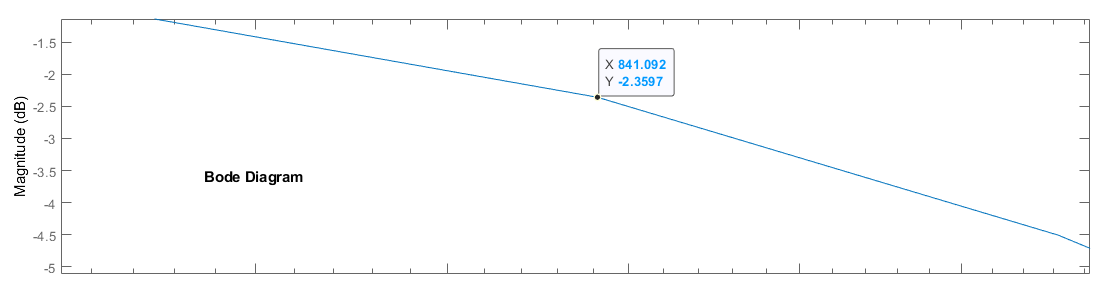

se observa que el filtro deja pasar mas de lo deseado, sin embargo, es una buena aproximacion teniendo encuenta que es un filtro digital.

#### G2

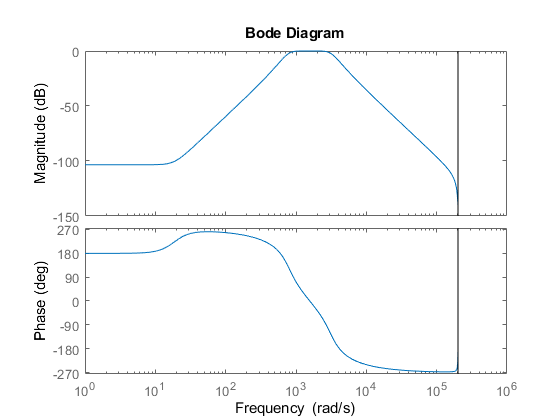

w2 = (2*pi*125)/fs ;
fi2 = (2*pi*125)/w2 ;
[numz2, denz2] = impinvar(num2, den2, fi2) ;
sysz2=tf(numz2, denz2, 1/fs) ;
bode(sysz2)

 para este caso la frecuencia de corte es de 125 Hz lo que equivale a 785 rad/s y 500 Hz que equivale a 3141,6 rad/s.

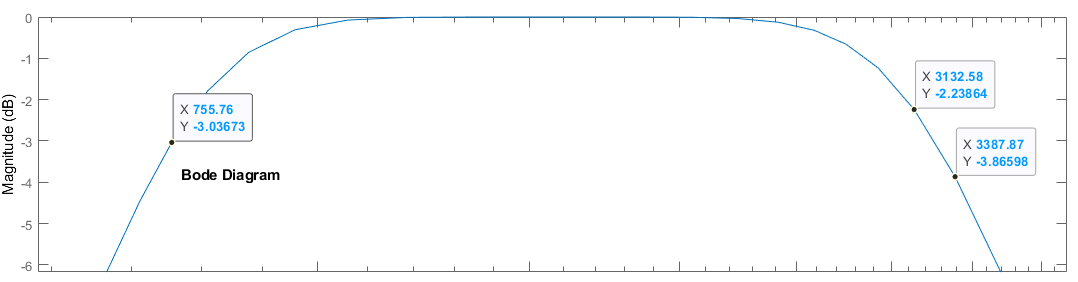

#### G3

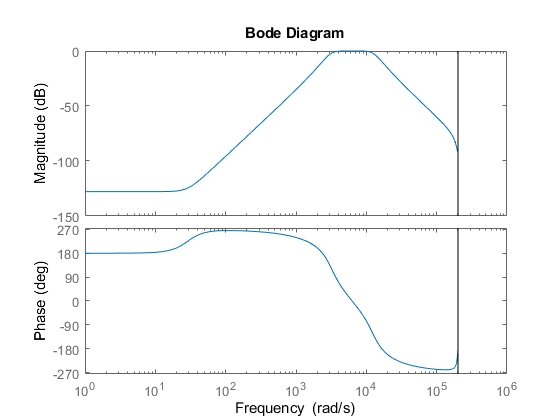

w3 = (2*pi*500)/fs ;
fi3 = (2*pi*500)/w3 ;
[numz3, denz3] = impinvar(num3, den3, fi3);
sysz3=tf(numz3, denz3, 1/fs) ;
bode(sysz3)

para este caso la frecuencia de corte es de 500 Hz lo que equivale a 3141,6 rad/s y 2000 Hz que equivale a 12566,4 rad/s.

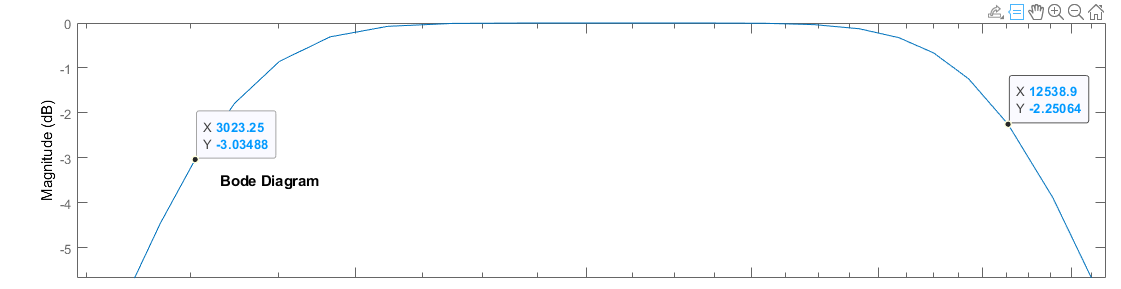

#### G4

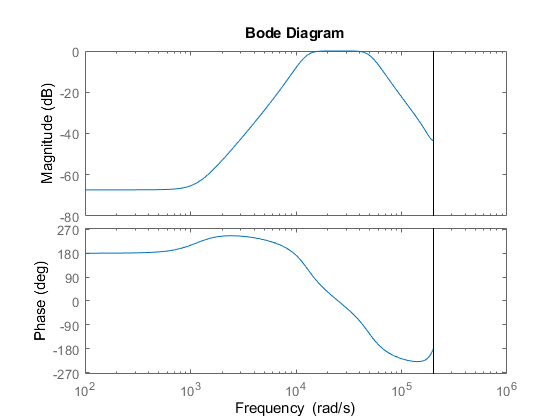

w4 = (2*pi*2000)/fs ;
fi4 = (2*pi*2000)/w4 ;
[numz4, denz4] = impinvar(num4, den4, fi4);
sysz4=tf(numz4, denz4, 1/fs) ;
bode(sysz4)

para este caso la frecuencia de corte es de 2000 Hz que equivale a 12566,4 rad/s y 8000 Hz que equivale a 50265,5 rad/s.

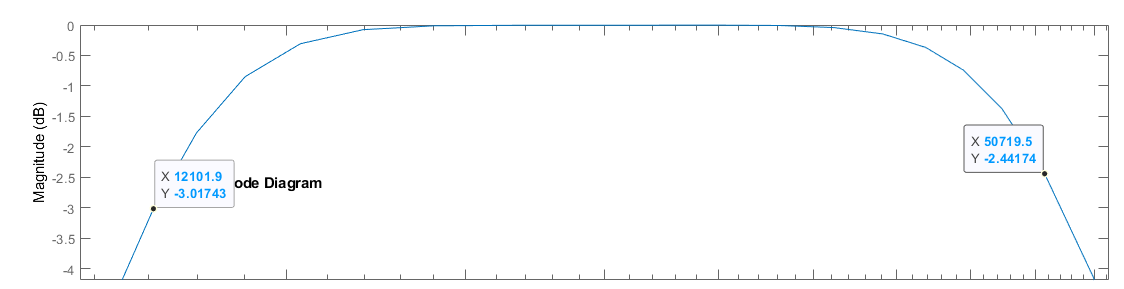

#### G5

No se hace, ya que la invariancia del impulso no sirve para filtros pasa altos.

### Transformación Bilineal

Al igual que para la funcion impinvar, para la funcion bilinear es necesario ingresar una frecuencia específica que sera la obtenida de aplicar la siguiente formula, 


$$\textrm{fs}=\frac{w_A }{2\tan \left(\frac{w_D }{2}\right)}$$


cabe resaltar que los valores deben estar en rad/s.

#### G1

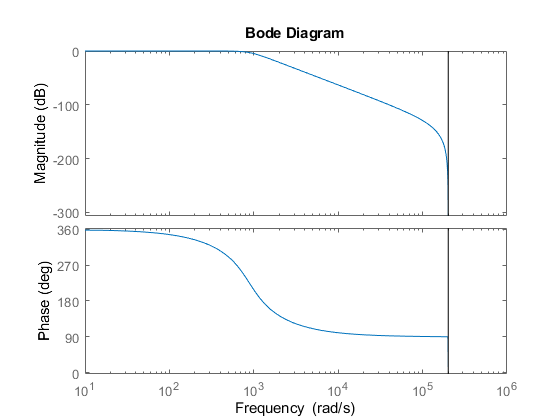

w1 = (2*pi*125)/fs ;
fb1 = (2*pi*125)/(2*tan((w1)/2)) ;
[numb1, denb1] = bilinear(num1, den1, fb1);
sysb1=tf(numb1, denb1, 1/fs);
bode(sysb1)

Para este caso la frecuencia de corte es de 125 Hz lo que equivale a 785 rad/s.

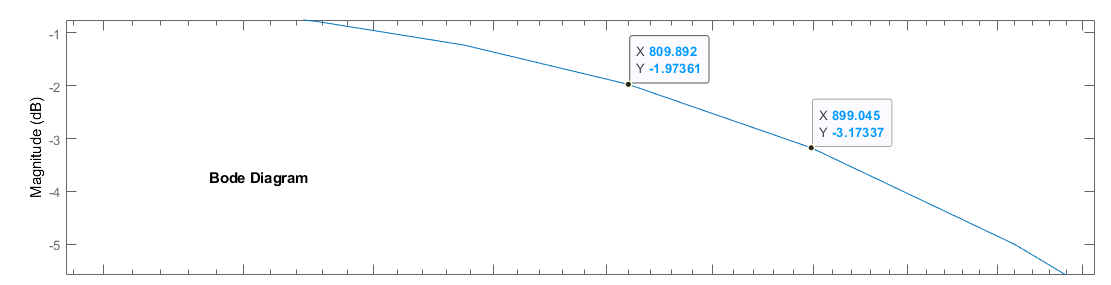

#### G2

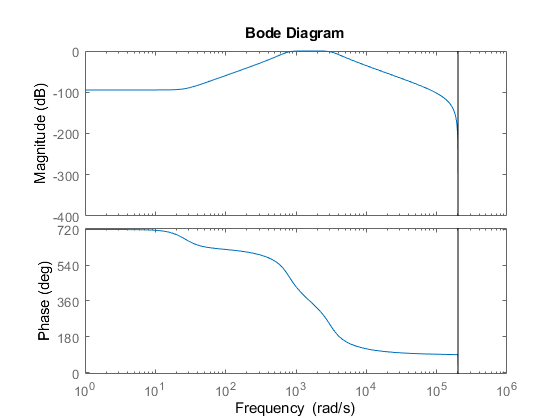

w2 = (2*pi*125)/fs ;
fb2 = (2*pi*125)/(2*tan(w2/2)) ;
[numb2, denb2] = bilinear(num2, den2, fb2);
sysb2=tf(numb2, denb2, 1/fs);
bode(sysb2)

 para este caso la frecuencia de corte es de 125 Hz lo que equivale a 785 rad/s y 500 Hz que equivale a 3141,6 rad/s.

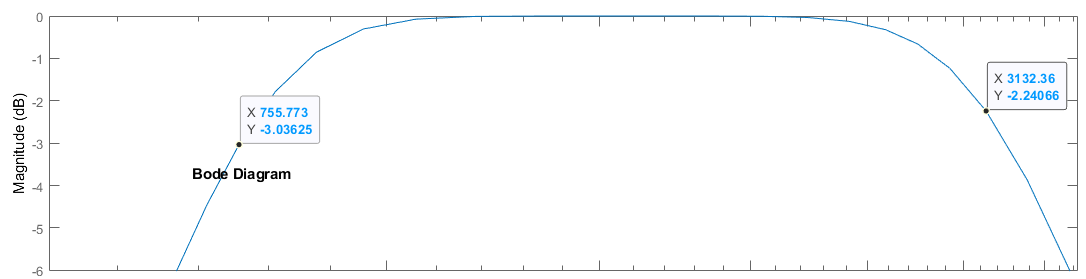

#### G3

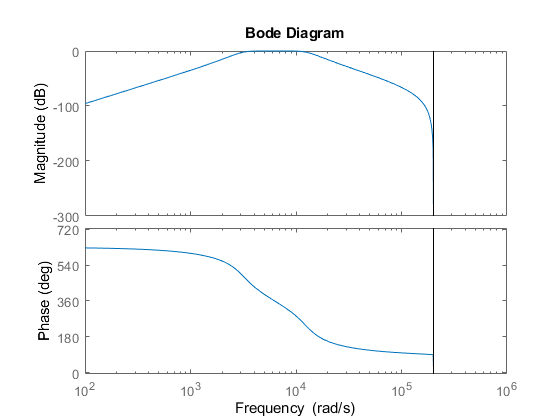

w3 = (2*pi*500)/fs ;
fb3 = (2*pi*500)/(2*tan(w3/2)) ;
[numb3, denb3] = bilinear(num3, den3, fb3);
sysb3=tf(numb3, denb3, 1/fs) ;
bode(sysb3)

para este caso la frecuencia de corte es de 500 Hz lo que equivale a 3141,6 rad/s y 2000 Hz que equivale a 12566,4 rad/s.

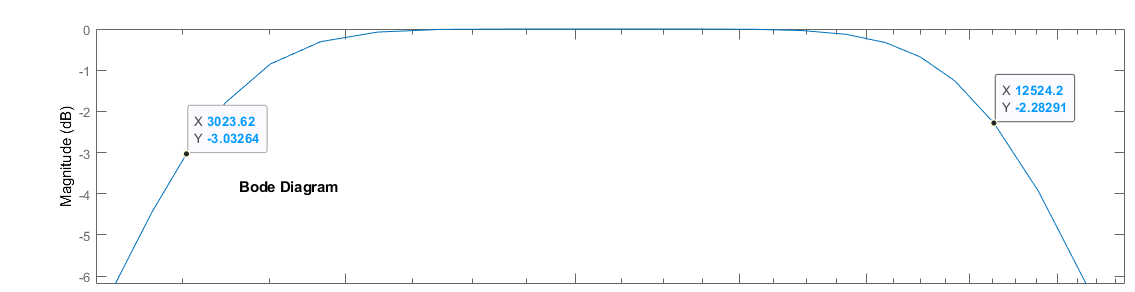

#### G4

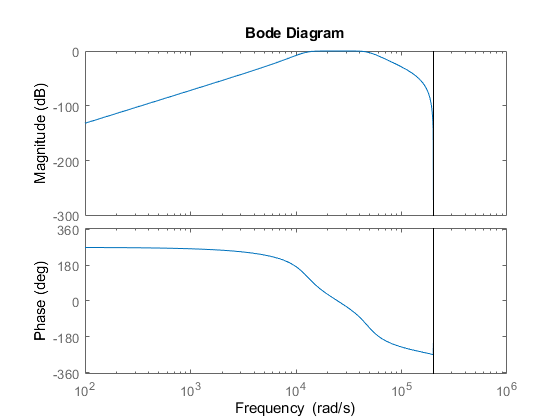

w4 = (2*pi*2000)/fs ;
fb4 = (2*pi*2000)/(2*tan(w4/2)) ;
[numb4, denb4] = bilinear(num4, den4, fb4);
sysb4=tf(numb4, denb4, 1/fs);
bode(sysb4)

para este caso la frecuencia de corte es de 2000 Hz que equivale a 12566,4 rad/s y 8000 Hz que equivale a 50265,5 rad/s.

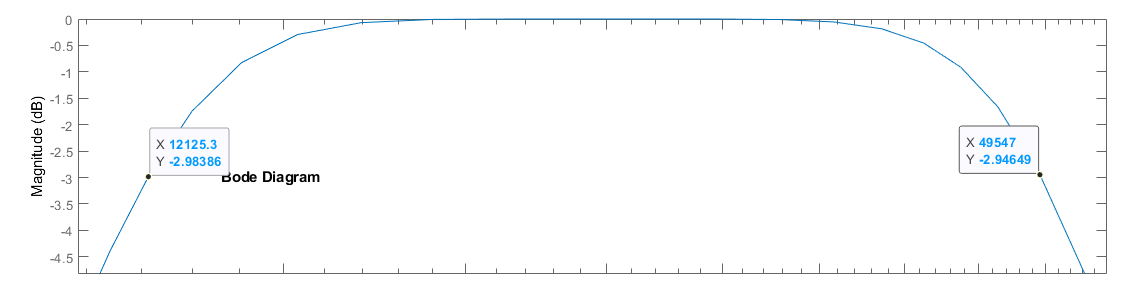

#### G5

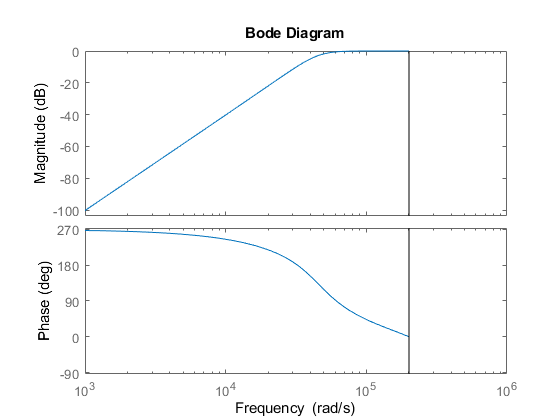

w5 = (2*pi*8000)/fs ;
fb5 = (2*pi*8000)/(2*tan(w5/2)) ;
[numb5, denb5] = bilinear(num5, den5, fb5);
sysb5=tf(numb5, denb5, 1/fs);
bode(sysb5)

para este caso la frecuencia de corte es de 8000 Hz que equivale a 50265,5 rad/s.

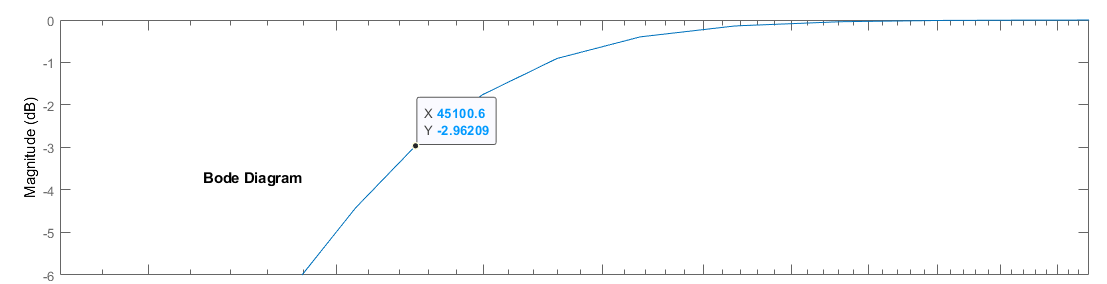

### Comparación de filtros

Para visualizar mejor y poder comparar más fácilmente ambos filtros los graficamos en una misma gráfica como se muestra a continuación:

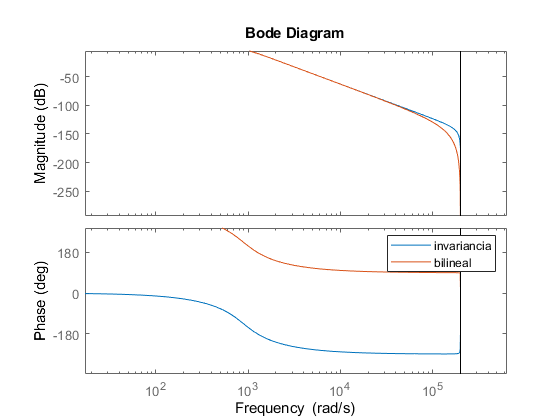

bode(sysz1, sysb1)
legend('invariancia', 'bilineal')

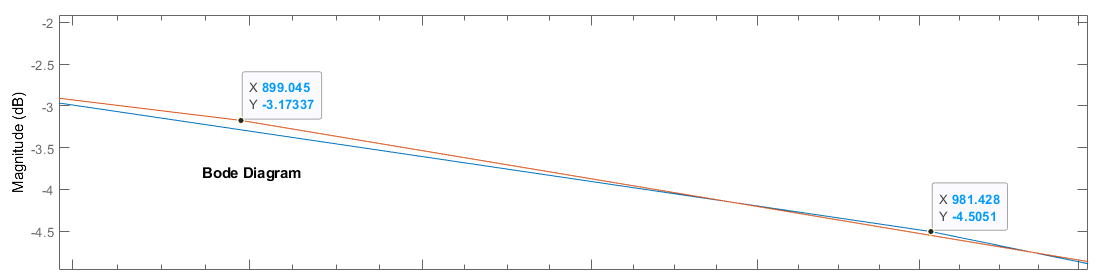

observamos que la linea azul(invariancia) llega primero a los 3 dB, por ende,es un mejor filtro. Sabiendo que este es un filtro pasabajos

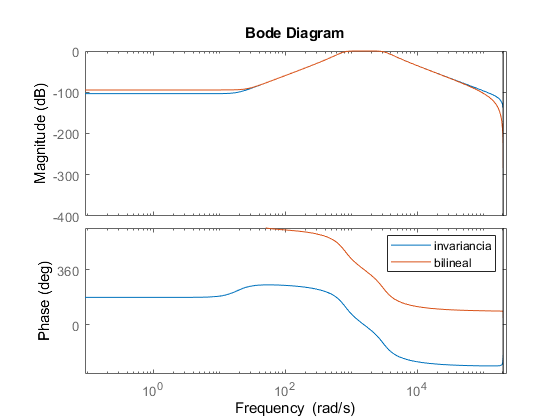

bode(sysz2, sysb2)
legend('invariancia', 'bilineal')

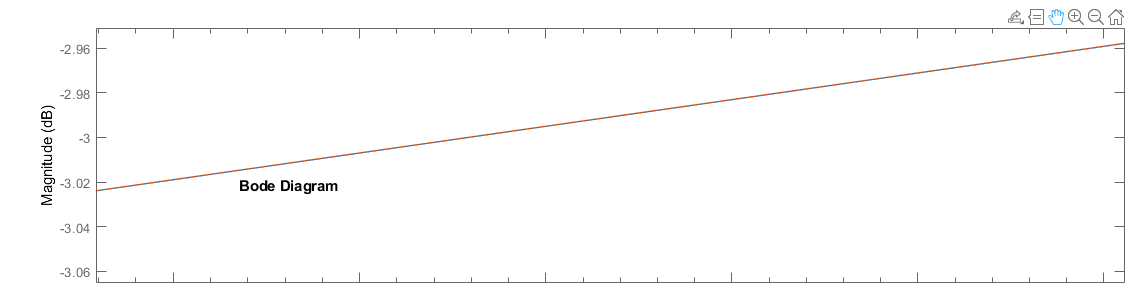

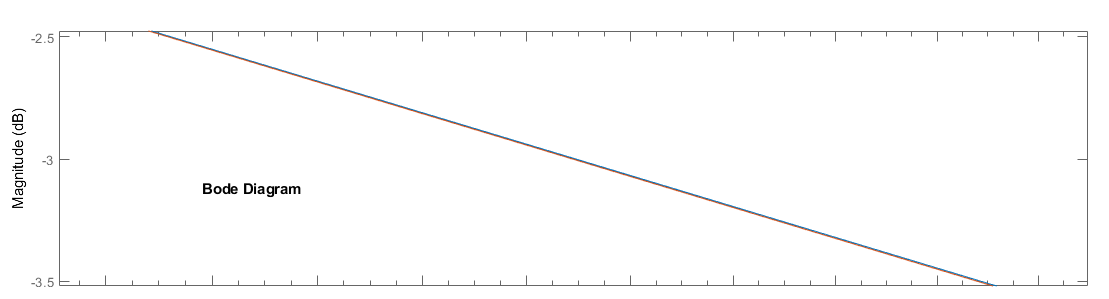

observamos que las líneas se sobreponen, por ende, se espera obtener los mismos resultados usando cualquiera de los filtros(invariancia o bilineal).

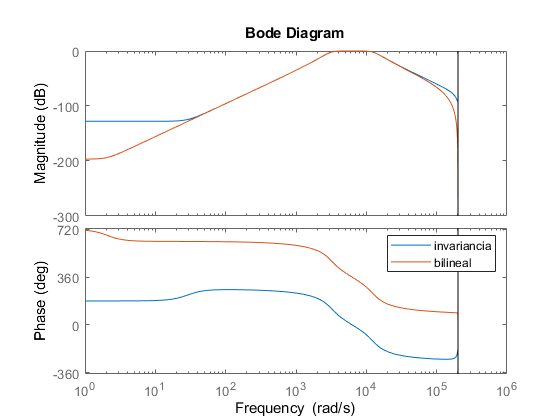

bode(sysz3, sysb3)
legend('invariancia', 'bilineal')

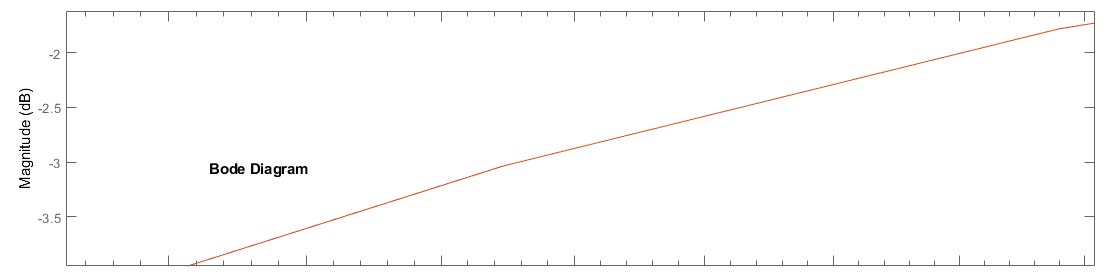

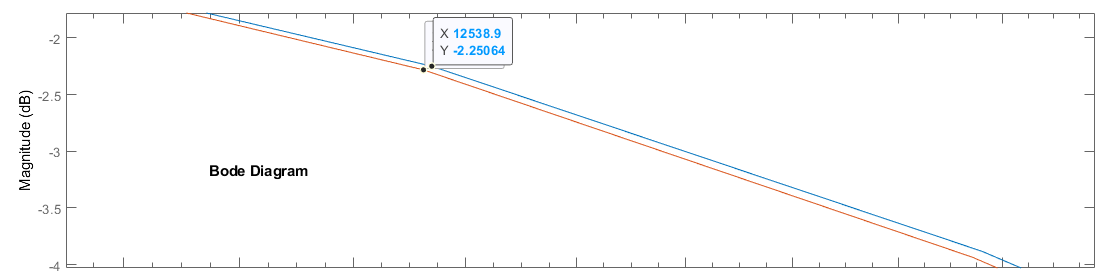

Para este caso el lado izquierdo de la grafica se sobrepone, mientras que el lado derecho la linea naranja(bilineal) llega primero a los 3 dB siendo esta mejor que la linea azul(invariancia). 

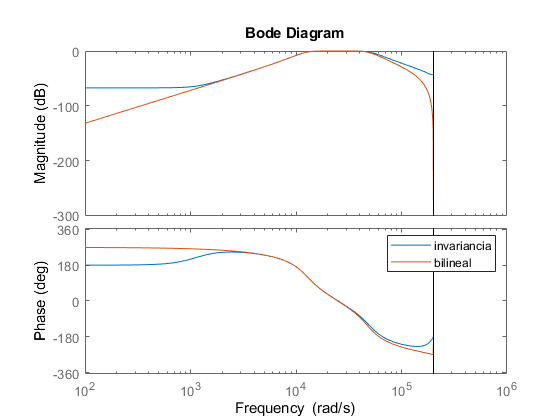

bode(sysz4, sysb4)
legend('invariancia', 'bilineal')

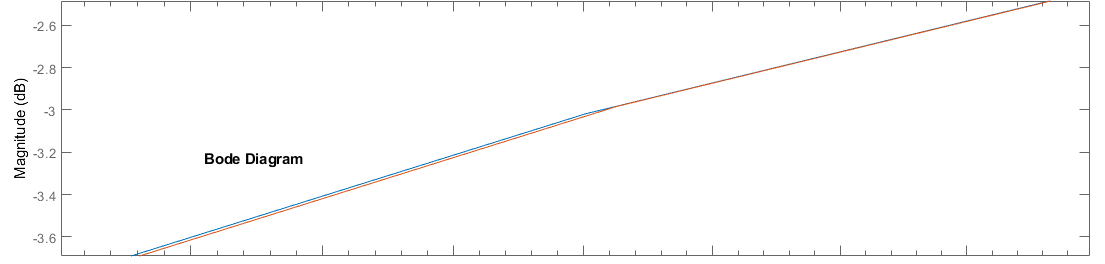

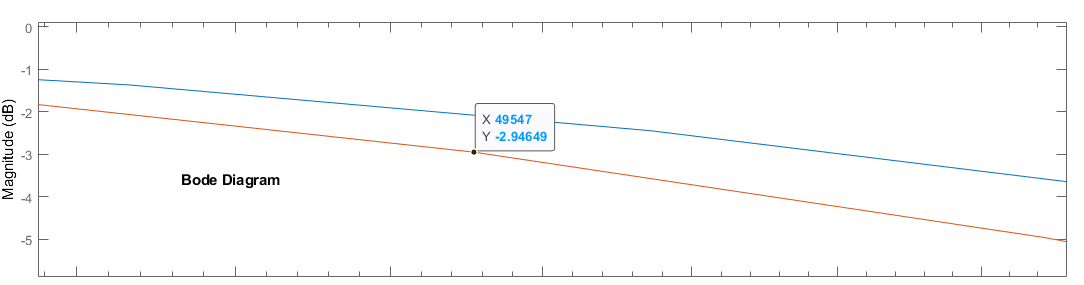

se puede observar que al lado izquierdo y lado derecho de la grafica la linea naranja(bilineal) llega primero a los 3 decibeles, siendo esto mas notable en el lado derecho, siendo este un mejor filtro.

Se plotea la parte inicial de la señal de entrada para tener una idea más clara de la forma de esta:

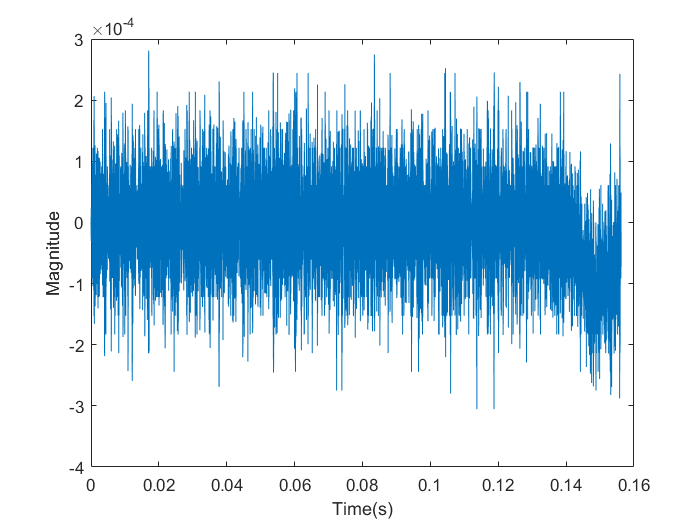

len = size(prueba, 1) ;
T = linspace(0, ceil(len/fs), len)' ;
plot(T(1:10000, 1), prueba(1:10000, 1))
xlabel('Time(s)')
ylabel('Magnitude')

### Implementación de los filtros

Se crea un sistema con cada filtro y se aplica a la señal de entrada:

#### G1

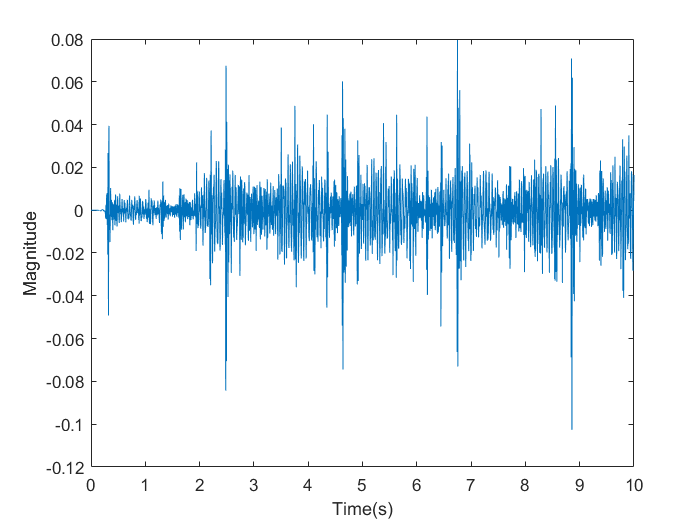

y1 = filtfilt(numb1, denb1, prueba);
plot(T, y1)
xlabel('Time(s)')
ylabel('Magnitude')

#### G2

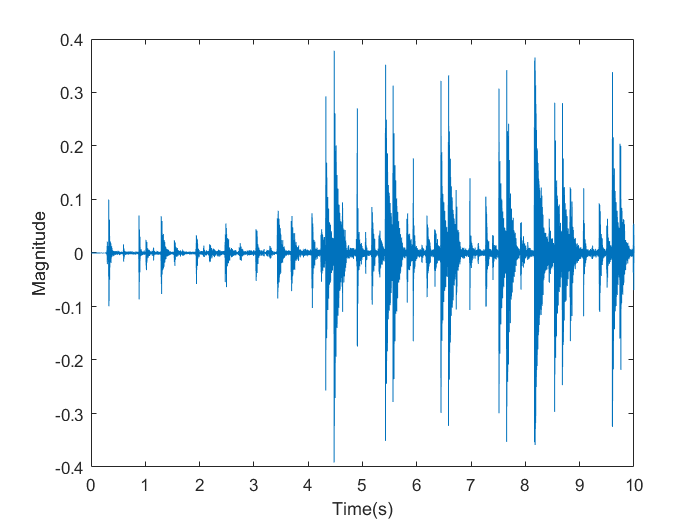

y2 = filtfilt(numb2, denb2, prueba);
plot(T, y2)
xlabel('Time(s)')
ylabel('Magnitude')

#### G3

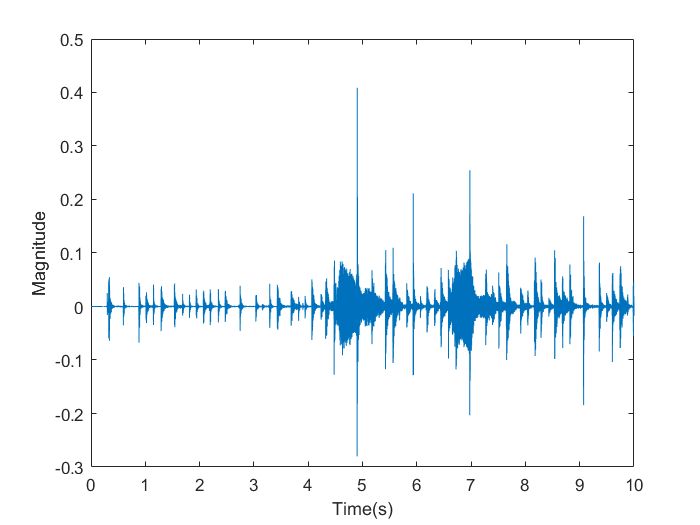

y3 = filtfilt(numb3, denb3, prueba);
plot(T, y3)
xlabel('Time(s)')
ylabel('Magnitude')

#### G4

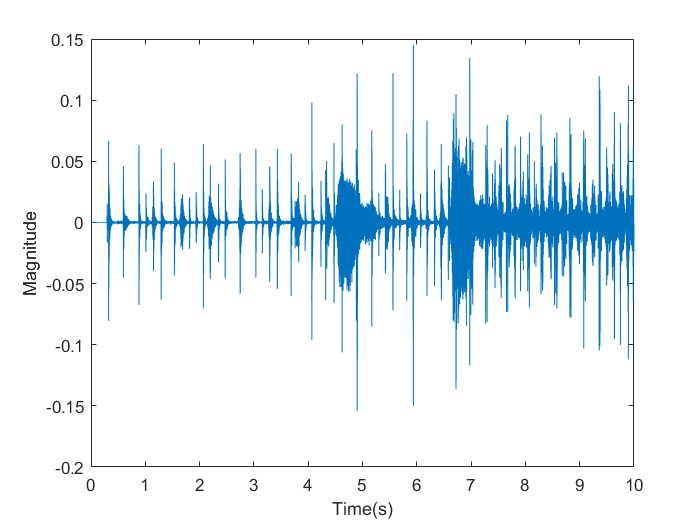

y4 = filtfilt(numb4, denb4, prueba);
plot(T, y4)
xlabel('Time(s)')
ylabel('Magnitude')

#### G5

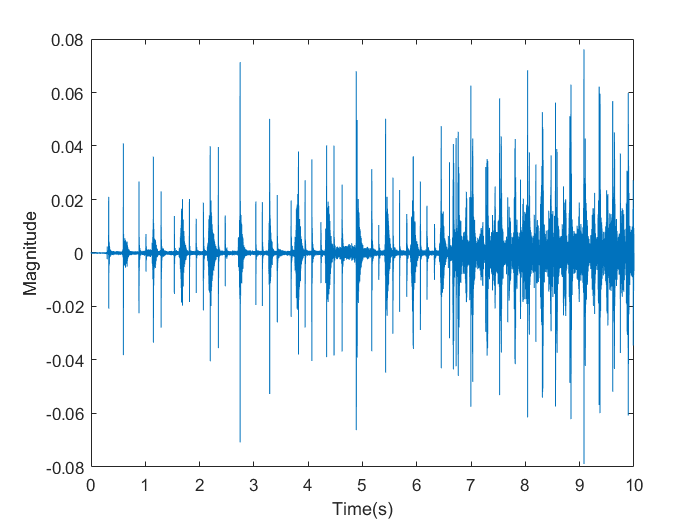

y5 = filtfilt(numb5, denb5, prueba);
plot(T, y5)
xlabel('Time(s)')
ylabel('Magnitude')

#### Ganancias

Finalmente se eligen los valores de las ganancias para combinar las señales de salida de los filtros:

G1 = 1; % 62.5Hz
G2 = 1; % 250Hz
G3 = 1; % 1kHz
G4 = 1; % 4kHz
G5 = 1; % 16kHz
 

se dan una serie de opciones preestablecidas para cada ganancia,

  G1 = 1 ; G2 = 1 ; G3 = 1 ; G4 = 1 ; G5 = 1 ;

  G1 = 1 ; G2 = 1 ; G3 = 1.3 ; G4 = 0.6 ; G5 = 0.6 ;

  G1 = 1 ; G2 = 0.4 ; G3 = 1.1 ; G4 = 1.6 ; G5 = 1.6 ;

  G1 = 1 ; G2 = 1.5 ; G3 = 0.8 ; G4 = 0.9 ; G5 = 0.9 ;

  G1 = 1 ; G2 = 1.3 ; G3 = 0.8 ; G4 = 1.3 ; G5 = 1.3 ;

se calcula la salida total,

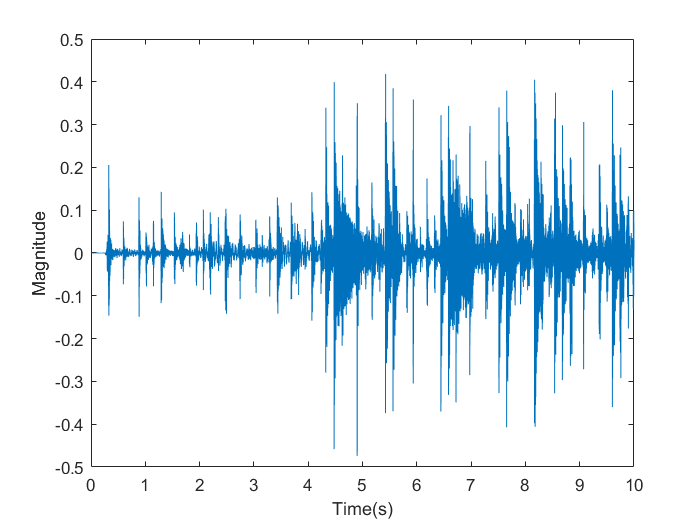

 
Y = G1*y1+G2*y2+G3*y3+G4*y4+G5*y5 ;
plot(T, Y)
xlabel('Time(s)')
ylabel('Magnitude')

se reproduce el audio,

 
if max(abs(Y)) > 1
    Y = Y/max(abs(Y)) ;
end
player = audioplayer(Y, fs)

player =   audioplayer with properties:

       SampleRate: 64000
    BitsPerSample: 16
      NumChannels: 1
         DeviceID: -1
    CurrentSample: 1
     TotalSamples: 640000
          Running: 'off'
         StartFcn: []
          StopFcn: []
         TimerFcn: []
      TimerPeriod: 0.0500
              Tag: ''
         UserData: []
             Type: 'audioplayer'


play(player)

  stop(player) 